# Mapa de Voronoi

clear all
close all
clc

**Mapa vacío**

map = zeros(256,256,3);
figure(1)

**Nodos aleatorios**

nodos = zeros(16,5);
for n = 1:16
    nodos(n,1)=round(256*rand);%Coordenada X
    nodos(n,2)=round(256*rand);%Coordenada Y
    nodos(n,3)=round(255*rand);%Color Rojo
    nodos(n,4)=round(255*rand);%Color Verde
    nodos(n,5)=round(255*rand);%Color Azul
end

**Escanear pixeles y asignar color**

s=size(map);
for j = 1:s(2)
    for i = 1:s(1)
        for d = 1:16
            dist(d)=sqrt((i-nodos(d,1))^2+(j-nodos(d,2))^2);
        end
        [M,I] = min(dist);
        map(i,j,1)=nodos(I,3);
        map(i,j,2)=nodos(I,4);
        map(i,j,3)=nodos(I,5);
    end
end

**Mostrar imagen**

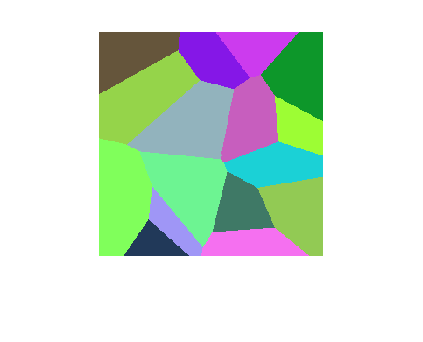

imshow(uint8(map))